%% ofdm_sim_sweep.m
clear; clc; close all;

% Parameters
N = 64; cp = 16; M = 4; k = log2(M);
numSymbols = 200;          % number of OFDM symbols to send end-to-end
SNRdB_list = 0:2:20;       % sweep SNRs
ber_vec = zeros(size(SNRdB_list));

rng(0); % reproducible

% Generate bits for all symbols
numBits = N * k * numSymbols;
bits = randi([0 1], numBits, 1);

% Map bits -> symbol indices (rows = symbols)
bits_matrix_all = reshape(bits, k, []).';   % (N*numSymbols) x k
sym_idx_all = bi2de(bits_matrix_all, 'left-msb');

% Split into symbols and OFDM modulate symbol-by-symbol
tx_symbols = reshape(sym_idx_all, N, []).';   % numSymbols x N
tx_time = [];
for s = 1:numSymbols
    sym = pskmod(tx_symbols(s,:).', M, pi/4, 'gray'); % column
    ofdm_time = ifft(sym, N);
    tx_sig_s = [ofdm_time(end-cp+1:end); ofdm_time];   % N+cp
    tx_time = [tx_time; tx_sig_s]; % append
end

% For each SNR, pass through AWGN and demod
for si = 1:length(SNRdB_list)
    SNRdB = SNRdB_list(si);
    rx_time = awgn(tx_time, SNRdB, 'measured');
    
    % RX: loop through symbols
    rx_sym_idx_all = zeros(numSymbols, N);
    ptr = 1;
    for s = 1:numSymbols
        rx_frame = rx_time(ptr + cp : ptr + cp + N - 1);
        ptr = ptr + (N + cp);
        Rf = fft(rx_frame, N);
        rx_idx = pskdemod(Rf, M, pi/4, 'gray');
        rx_sym_idx_all(s, :) = rx_idx.'; % row
    end
    
    % Convert back to bits
    rx_sym_idx_col = reshape(rx_sym_idx_all.', [], 1); % N*numSymbols x 1
    rx_bits_matrix = de2bi(rx_sym_idx_col, k, 'left-msb');
    rx_bits = reshape(rx_bits_matrix.', [], 1);
    
    % BER
    [~, ber] = biterr(bits, rx_bits);
    ber_vec(si) = ber;
    fprintf('SNR= %2d dB -> BER = %.3e\n', SNRdB, ber);
end

SNR=  0 dB -> BER = 1.586e-01
SNR=  2 dB -> BER = 1.027e-01
SNR=  4 dB -> BER = 5.641e-02
SNR=  6 dB -> BER = 2.246e-02
SNR=  8 dB -> BER = 6.094e-03
SNR= 10 dB -> BER = 9.375e-04
SNR= 12 dB -> BER = 3.906e-05
SNR= 14 dB -> BER = 0.000e+00
SNR= 16 dB -> BER = 0.000e+00
SNR= 18 dB -> BER = 0.000e+00
SNR= 20 dB -> BER = 0.000e+00


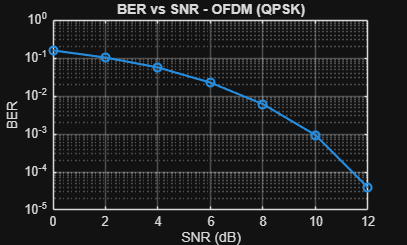


% Plot BER curve
figure; semilogy(SNRdB_list, ber_vec, '-o','LineWidth',1.6); grid on;
xlabel('SNR (dB)'); ylabel('BER'); title('BER vs SNR - OFDM (QPSK)');
saveas(gcf,'ber_vs_snr.png');

% Save results
csvwrite('ber_vs_snr.csv', [SNRdB_list.' ber_vec.']);
